## Resitting exam 04-07-2023

### Problem 1

We wish to study how the temperature varies with depth in an open air water tank. For that, we take a vertical segment from the bottom to the surface at the tank midpoint, and mesh it with 3 linear elements of equal length as shown in the image.

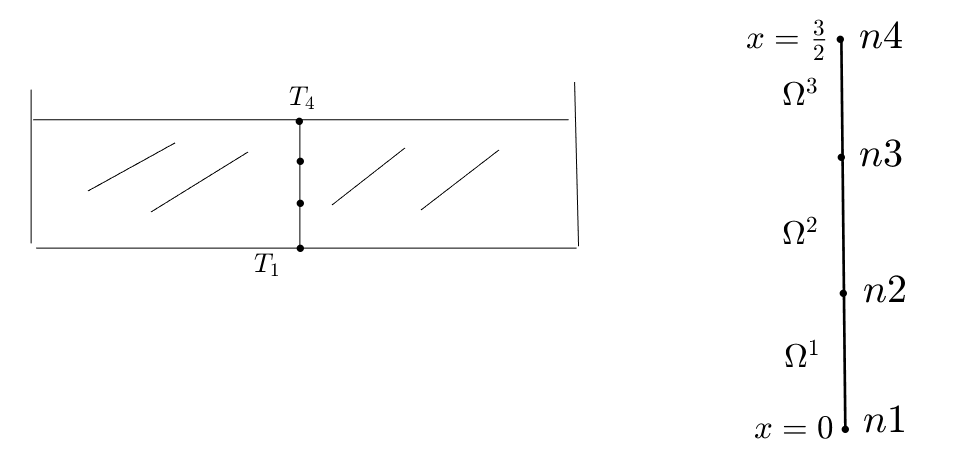

The water temperature follows the 1D Poisson equation $-k_{c}\frac{\mathrm{d}^{2} T}{\mathrm{d} x^{2}} = f(x)$ where kc is the thermal conductivity of water, and the internal heat source is the warming of the tank, with a power density $f (x) = (8x + 4)\frac{\text{W}}{\text{m}^3}$ ($x$ is the height above the tank bottom in $\text{m}$).

(a) (3 points)Take as thermal conductivity of water $k_{c} = 0.57\frac{\text{W}}{\text{m}^{\circ}\text{C}}$. Find the sum of all coefficients of the stiffness matrix $K$. 

- 
$$0$$
 
$$\surd$$


- 
$$1.14$$


- 2.28

- 13.68

- Leave it empty (no penalty)

*Hint. *$K_{23} = -1.14$. 

**Solution.** 

Position of the nodes: 


$$x_{1} = x_{1}^{1} = 0,\quad x_{2} = x_{2}^{1} = x_{1}^{2} = 1/2,\quad x_{3} = x_{2}^{2} = x_{1}^{3} =1 ,\quad x_{4} = x_{3}^{2}=3/2.$$


Lenght of the elements:


$$h^{e} = x_{2}^{e} - x_{1}^{e} = 1/2,$$


for $e = 1, 2, 3$. Shape functions:


$$ \Psi_{1}^{e}(x) = \frac{x-x_{2}^{e}}{x_{1}^{e}-x_{2}^{e}} = \frac{1}{h^{e}}\left(x_{2}^{e} - x\right)= 2\left(x_{2}^{e} - x\right), 
\qquad
\Psi_{2}^{e}(x) = \frac{x-x_{1}^{e}}{x_{2}^{e}-x_{1}^{e}} = \frac{1}{h^{e}}\left(x-x_{1}^{e}\right)= 2\left(x-x_{1}^{e}\right),$$


for $e = 1, 2, 3$. Then, the components of the local stiffness matrices are,


$$K_{ij}^{e} = \int_{x_{1}^{e}}^{x_{2}^{e}} k_{c}\frac{\mathrm{d}\Psi_{i}^{e}}{\mathrm{d} x}(x) \frac{\mathrm{d}\Psi_{j}^{e}}{\mathrm{d} x}(x) \,\mathrm{d} x = (-1)^{i+j} k_{c}\int_{x_{1}^{e}}^{x_{2}^{e}} \frac{\mathrm{d} x}{\left(h^{e}\right)^{2}} = (-1)^{i+j} k_{c} \frac{x_{2}^{e} - x_{1}^{e}}{\left(h^{e}\right)^{2}} = k_{c}\frac{(-1)^{i+j}}{h^{e}} = 2(-1)^{i+j} k_{c},$$


for $e = 1, 2, 3$, and $i,j = 1,2$. So,

 $K^{e} = 2k_{c}\left(\begin{array}{rr} 1 & -1\\ -1 & 1\end{array}\right)$, $e = 1,2,3$.

$K^{e} = 2k_{c}\left(\begin{array}{rr} 1 & -1\\ -1 & 1\end{array}\right)$,

for $e = 1, 2, 3$. *Remark: *actually*, *since the coefficients are constant, we could have used straightforward the formulas discussed in the class notes.

- Global stiffness matrix and global load vector:


$$K = 2 k_{c}\left(\begin{array}{rrrr}
1 & -1 & &\\
-1 & 2 & -1 &\\
    & -1 & 2 & -1\\
   &      & -1 & 1
\end{array}
\right), \quad
F = \left(\begin{array}{c}
F_{1}^{1}\\
F_{2}^{1} + F_{1}^{2}\\
F_{2}^{2} + F_{1}^{3}\\
F_{2}^{3}
\end{array}
\right) =
\left(
\begin{array}{c}
3/2\\
3/2 + 5/2\\
5/2 + 7/2\\
7/2
\end{array}
\right) =
\left(
\begin{array}{c}
3/2\\
4\\
6\\
7/2
\end{array}
\right).$$


Therefore $\sum\limits_{i,j=1}^{4} K_{ij} = 0$, and $K_{23} = -2k_{c} = -1.14$.

(b) (4 points) Approximate the thermal conductivity of water as $k_{c} = 0.5\frac{\text{W}}{\text{m}^{\circ}\text{C}}$. The temperature  has been found to be $T_{1} = 20^{\circ}\text{C}$at the nottom of the tank and $T_{4} = 25.3^{\circ}\text{C}$ at the surface. Assume that there is no convetion, and consider the power density function $f$ on each element $[x_{i}, x_{i+1}]$ as **constant**, wiith its midpoint value $f\left(\frac{x_{i} + x_{i+1}}{2}\right)$. Find the heat flow $Q_{4}$.

- 
$$-7.0667$$

$$\surd$$


- 
$$-7.5$$


- 
$$7.5$$


- 
$$7.0667$$


- Leave it empty (no penalty)

*Hint.* $Q_{1} = -7.9333$.

**Solution.** 

Local load vectors:


$$\begin{array}{rcl}
F_{1}^{e}
 \!\!\!\!\! & = & \!\!\!\!\!
\int_{x_{e}}^{x_{e+1}} f(x)\Psi_{1}^{e}(x)\,\mathrm{d} x =
f\left(\frac{x_{e} + x_{e+1}}{2}\right)\int_{x_{e}}^{x_{e+1}}\,\, 
\frac{x_{e+1} - x}{h^{e}}\,\mathrm{d} x = 
\frac{1}{h^{e}}f\left(\frac{x_{e} + x_{e+1}}{2}\right)
\int_{0}^{h^{e}}\!\!t \,\mathrm{d}t\\
\!\!\!\!\! & = & \!\!\!\!\!
\frac{1}{h^{e}}f\left(\frac{x_{e} + x_{e+1}}{2}\right) \frac{\left(h^{e}\right)^{2}}{2} =
\frac{h^{e}}{2}f\left(\frac{x_{e} + x_{e+1}}{2}\right) =
\frac{h^{e}}{2}\left(8\frac{x_{e} + x_{e+1}}{2} + 4\right) = 
1 + x_{e} + x_{e+1} = F_{2}^{e},\quad e =1,2,3.
\end{array}$$


  So $F^{e} = \left(\begin{array}{c} 1 + x_{e} + x_{e+1}\\ 1 + x_{e} + x_{e+1}\end{array}\right) = \frac{2 e + 1}{2}\left(\begin{array}{c} 1\\ 1\end{array}\right)$ $e = 1,2,3$. Thus, the global load vector is given by


$$F = \left(\begin{array}{c}
F_{1}^{1}\\
F_{2}^{1} + F_{1}^{2}\\
F_{2}^{2} + F_{1}^{3}\\
F_{2}^{3}
\end{array}
\right) =
\left(
\begin{array}{c}
3/2\\
3/2 + 5/2\\
5/2 + 7/2\\
7/2
\end{array}
\right) =
\left(
\begin{array}{c}
3/2\\
4\\
6\\
7/2
\end{array}
\right),$$


so the global (coupled) system is:


$$2k_{c}\left(\begin{array}{rrr}
-1 & 1 & \\
-1 & 2 & -1 &\\
   & -1 & 2 & -1\\
   &     & -1 & 1
\end{array}
\right)
\left(\begin{array}{c}
T_{1}\\
T_{2}\\
T_{3}\\
T_{4}
\end{array}
\right) = 
\left(\begin{array}{c}
Q_{1}\\
Q_{2}\\
Q_{3}\\
Q_{4}
\end{array}
\right) + 
\left(\begin{array}{c}
3/2\\
 4\\
 6\\
7/2
\end{array}
\right).$$


Now with $k_{c} = 0.5$. Boundary conditions:

- Natural BC: $Q_{2} = Q_{3} = 0$.

- Essential: $T_{1} = 20$, $T_{4} = 25.3$.

Therefore, the reduced system turns out to be:


$$\left(\begin{array}{rr} 2 & -1\\ -1 & 2\end{array}\right)\left(\begin{array}{c} T_{2}\\ T_{3}\end{array}\right) = \left(\begin{array}{c} 4 + T_{1}\\ 6 + T_{4}\end{array}\right).$$


And we can solve it, for axample, by Cramer's rule,


$$\begin{array}{c}
T_{2} = \frac{
\left|\begin{array}{rr}
4 + T_{1} & -1\\
6 + T_{4} & 2
\end{array}
\right|%
}
{
\left|\begin{array}{rr}
2 & -1\\
-1 & 2
\end{array}
\right|
} = \frac{14 + 2T_{1} + T_{4}}{3} =
\frac{14+40 + 25.3}{3} = \frac{79.3}{3} = 26.4\overline{3},
%
\\
T_{3}  =  \frac{
\left|\begin{array}{rr}
2 & 4 + T_{1}\\
-1 & 6 + T_{4}
\end{array}
\right|%
}
{
\left|\begin{array}{rr}
2 & -1\\
-1 & 2
\end{array}
\right|%
} = \frac{16 + T_{1} + 2T_{4}}{3} =
\frac{16+20+50.6}{3} =
\frac{86.6}{3} = 28.8\overline{6}.
\end{array}$$


Finally, we can substitute these solutions for $T_{3}$ and $T_{3}$ in the 1st and the 4th equation on the couple and solve for $Q_{1}$ and $Q_{4}$ respectively. Therefore,


$$\begin{array}{c}
Q_{1} = T_{1} - T_{2} - \frac{3}{2} = T_{1} - \frac{2T_{1} + T_{4} -14}{3} - \frac{3}{2} =
\frac{2T_{1} - 2T_{4} - 37}{6} =
\frac{40 - 50.6 - 37}{6} = 
 -\frac{47.6}{6} = -7.9\overline{3},\\
Q_{4} = T_{4} -T_{3} - \frac{7}{3} = T_{4} - \frac{T_{1} + 2T_{4} - 16}{3} - \frac{7}{2} = \frac{2T_{4} - 2T_{1} - 53}{6} =
\frac{50.6 - 40 - 53}{6} = -\frac{42.4}{6} = -7.0\overline{6}.
\end{array}$$


Let's do this with Matab code:

clearvars
close all

nodes = (0:0.5:1.5)';
elem = [(1:3)', (2:4)'];

numNodes = size(nodes, 1);
numElem = size(elem, 1);

kc = 0.5;
Ke = 2*kc*[1, -1; -1, 1];

K = zeros(numNodes);
F = zeros(numNodes, 1);

for e = 1:numElem
    rows = [elem(e,1), elem(e,2)];
    cols = rows;
    K(rows,cols) = K(rows, cols) + Ke;
    Fe = (1 + nodes(e,1) + nodes(e+1,1))*[1; 1];
    F(rows) = F(rows) + Fe;
end

% Boundary conditions
Q = zeros(numNodes,1);

fixedNodes = [1, 4];
freeNodes = setdiff(1:numNodes, fixedNodes);

% Natural BC
Q(freeNodes) = 0; % Not necessary, since Q has been initialised to 0

% Essential BC
T1 = 20.0;
T4 = 25.3;
u = zeros(numNodes,1);
u(1) = T1;
u(4) = T4;

% Reduced system
Fm = Q(freeNodes) + F(freeNodes) - K(freeNodes, fixedNodes) * u(fixedNodes);
Km = K(freeNodes, freeNodes);

% Solve the reduced system
um = Km\Fm;

% Include the solution for the free nodes in the corresponding components
% of the global solution
u(freeNodes) = um;


% Post process
% We compute Q's
Q = K*u - F;

% and table thesolutions
sz = [numNodes, 3];
varTypes = ["int64", "double", "double"];
varNames = ["node", "T(ºC)", "Q"];
sols = table('Size', sz,...
    'VariableTypes', varTypes,...
    'VariableNames', varNames);
sols(:,1) = table((1:numNodes)'); sols(:,2) = table(u); sols(:,3) = table(Q); 
sols

sols = 4×3 table
    node    T(ºC)          Q     
    ____    ______    ___________

     1          20        -7.9333
     2      26.433    -3.5527e-15
     3      28.867    -3.5527e-15
     4        25.3        -7.0667


(c) (3 points) Keep the value $k_{c} = 0.5\frac{\text{W}}{\text{m}^{\circ}\text{C}}$ for the thermal conductivity of water. Now assume the same constant approximation for$f$as in the previous section and that the temperature at the bottom  of the tank is $T_{1} = 20^{\circ}\text{C}$. Let us consider now that there is convection on the tank surface (that is, in node $4$), following tjhe law $k_{c}\frac{\mathrm{d} T}{\mathrm{d} x} + \beta\left( T - T_{\infty}\right) = 0$, with air temperature $T_{\infty} = 22^{\circ}C$but with unknown value for $\beta$. Deduce the value of $\beta$ from the fact that the temperature is $T_{4} = 25.3^{\circ}\text{C}$. Approximate$f$as in (b).

- 
$$2.1613$$


- 
$$2.1423$$


- 
$$2.1414$$

$$\surd$$


- 2.0557

- Leave it empty (no penalty)

*Hint.* Solve the FEM problem with convection given by $\beta$ and *unknown* $T_{4}$. You will get a value for $T_{4}$ wich will depend on $\beta$.

**Solution.** 

Now, since $Q_{4} = k_{c}\frac{\mathrm{d} T}{\mathrm{d} x}(x_{4}) = -\beta\left(T_{4} - T_{\infty}\right) = -\beta\left(T_{4} - 22\right)$, it is readily seen that the reduced system can be written as 


$$\left(\begin{array}{rrr}
2  & -1 &    \\
-1 &  2 & -1\\
    &  -1 & 1
\end{array}
\right)
\left(
\begin{array}{c}
T_{2}\\
T_{3}\\
T_{4}
\end{array}
\right) =
\left(
\begin{array}{c}
 4 + T_{1}\\
6\\
-\beta\left(T_{4}-22) + 7/2
\end{array}
\right),

$$


and that it can be arranged in the form,


$$\left(\begin{array}{rrc}
2  & -1 &   0\\
-1 &  2 &   0\\
 0  &  -1 & T_{4} - 22 
\end{array}
\right)
\left(
\begin{array}{c}
T_{2}\\
T_{3}\\
\beta
\end{array}
\right) =
\left(
\begin{array}{c}
 4 + T_{1}\\
6 + T_{4}\\
 7/2 - T_{4}
\end{array}
\right),$$


with $T_{1} = 20^{\circ}\text{C}$, and $T_{4}=25.3^{\circ}\text{C}$. We note that the 1st two equations of the above system are decoupled from the 3rd one ($\beta$ doesn't appear neither in the first nor in the second equation), and that their soluions are the same as in (b), i.e.,


$$T_{2} =  \frac{14 + 2T_{1} + T_{4}}{3} = 26.4\overline{3},\qquad
T_{3}  = \frac{16 + T_{1} + 2T_{4}}{3} = 28.8\overline{6}.
$$


And we can substitute $T_{1}$, $T_{3}$, and $T_{4}$ in the 3rd equation and solve for $\beta$. This yields, 


$$\beta = \frac{53 + 2T_{1} - 2T_{4}}{4\left(T_{4} - 22\right)} = 
\frac{53 + 40 - 50.6}{6\times 3.3} =
\frac{21.1}{9.9} = 2.\overline{14}.$$


Using Matlab we can check the solution of the system:

Km = [2, -1, 0; -1, 2, 0; 0, -1, T4 - 22];
Fm = [4 + T1; 6 + T4; 3.5 - T4];
u = Km\Fm;

% Table the solutions
sz = [3, 2];
varTypes = ["string", "double"];
varNames = [" ", "  "];
sols = table('Size', sz,...
    'VariableTypes', varTypes,...
    'VariableNames', varNames);
sols(:,1) = table(["T2"; "T3"; "beta"]); sols(:,2) = table(u);
sols

sols = 3×2 table
                    
    ______    ______

    "T2"      26.433
    "T3"      28.867
    "beta"    2.1414
